# Inner Controller Development

## Setup

load 'quad_copter_models.mat';
USE_REAL_DATA = true;

We want to develop the fastest controller for the system that we can possibly get. This is a two step process. First we increase the bandwidth of the innner system to the limit and then work on the outer controller. Before we start we need to devise a reference model.

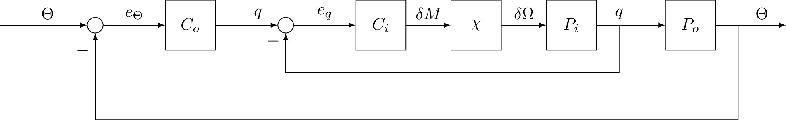

We have a set of I/O data measured from the input of the `PitchRateModel` bock to it's output. The input is $\delta \Omega$, the difference between the speeds of the front and rear propellers. For more information on the origin of this choice read [this](http://thesis.comkieffer.com/making-sense-of-the-data.html) article. Since writing that article the data has been processed to convert it to absolute values. The output is the angular velocity of the quad copter. 

However we  have chosen to consider the `Mixer` and the `PitchRateModel` as a single `Plant` block for the VRFT to remove the effect of the Mixer from the controller. 

PlantModel = PitchRateModel * Mixer; 
PlantModel_dt = c2d(PlantModel, Ts); 

## Reference Model. 

There is no sense in using a complex model. The simplest model that lets us tune damping and bandwidth seperatly is a 2nd order model. We will start with a low cut-off frequency and move up until we reach the upper limit. 

Note: at this time we are neglecting the effect of noise on the data and pretending that the model has no delay. The closed loop system has some delay (about 40ms or 4 samples) however the open loop data we have can be considered delay-free.

max_inner_bw = 30;

InnerReferenceModel = mk_2nd_order(max_inner_bw, .7);
InnerReferenceModel_dt = c2d(InnerReferenceModel, Ts);

## Looking at the data

vrft_data = struct();
ol_data = load('dati_id_ol_scalati.mat');

vrft_data.time      = ol_data.t;
vrft_data.dOmega    = ol_data.u;
vrft_data.q_dot     = ol_data.yi;
vrft_data.type      = 'Experimental';


The data we have goes from $\delta \Omega$ to $\dot{q}$. However, for the VRFT, we want the data from $\delta M$to $\dot{q}$. This means that we need to include the effect of the `Mixer` in the data. Since the Mixer is upstream  of our input we have:


$$d\Omega = \Phi \cdot d M \rightarrow d M = \Phi^{-1} \cdot d\Omega$$


vrft_data.dM = lsim(Mixer^-1, vrft_data.dOmega, vrft_data.time);
vrft_data.q_dot_sim = lsim(PlantModel, vrft_data.dM, vrft_data.time);

Let's take a look at what we have.

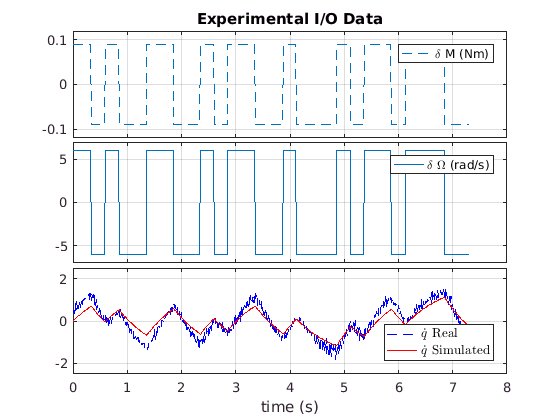

figure()
    subplot 311
        plot(vrft_data.time, vrft_data.dM, '--'); 
        legend('\delta M (Nm)'); ylim([-.12, .12]);
        title('Experimental I/O Data');
        
    subplot 312 
        plot(vrft_data.time, vrft_data.dOmega); 
        legend('\delta \Omega (rad/s)'); ylim([-7, 7]);
    subplot 313
        plot(vrft_data.time, vrft_data.q_dot, '--b', ...
             vrft_data.time, vrft_data.q_dot_sim, 'r'); 
        legend({'$$\dot{q}$$ Real', '$$\dot{q}$$ Simulated'}, ...
            'Location', 'southEast', 'Interpreter', 'latex', 'FontSize', 10); 
        xlabel('time (s)'); ylim([-2.5, 2.5]);
condense_subplots('tight', true)        

We are most interested in the third plot. This plot shows the real (measured) angular velocity ($\dot{q}$) and the simulatedangular velocity. These two values seem to be in accordance. So far, so good.

## VRFT Time !

Note: `VRFT1_ry_theta` is an extension of the `VRFT1_ry` method that also exposes the value of the parameter vector. The only changes from the original file are related to this. 

We need to account for the fact that the data is noisy. This is done by setting $k$, the complexity of the ARX model used to estimate the noise. We use an experimental procedure for this and simply pick the value that minimises the overshoot. For a bandwidth of $10\ rad/s$ we have a k value of 6 for example.

% To identify the optimal noise order run |inner_vrft_tune_k.mlx|
OptimalNoiseOrder = 9;

[DefaultController, ~] = ...
    VRFT1_ry_theta(vrft_data.dM, vrft_data.q_dot, InnerReferenceModel_dt, ...
                   PIDControllerClass_dt, [], [], []);
[OptimalInnerController, inner_pid_params] = ...
    VRFT1_ry_theta(vrft_data.dM, vrft_data.q_dot, InnerReferenceModel_dt, ...
                   PIDControllerClass_dt, [], OptimalNoiseOrder, []);

    

cloop_default = loopsens(PlantModel_dt, DefaultController); 
InnerLoop_VRFT_default = cloop_default.Ti;

fprintf('PID Controller params: Kp = %.3f, Ki = %.3f, Kd = %.3f', ...
    inner_pid_params(1), inner_pid_params(2), inner_pid_params(3));

PID Controller params: Kp = 0.406, Ki = 0.438, Kd = -0.001


inner_pid_params(3) = max(inner_pid_params(3), 0);
OptimalInnerController = pid(...
    inner_pid_params(1), inner_pid_params(2), inner_pid_params(3), Tf, Ts);

fprintf('Corrected PID Controller params: Kp = %.3f, Ki = %.3f, Kd = %.3f', ...
    inner_pid_params(1), inner_pid_params(2), inner_pid_params(3));

Corrected PID Controller params: Kp = 0.406, Ki = 0.438, Kd = 0.000

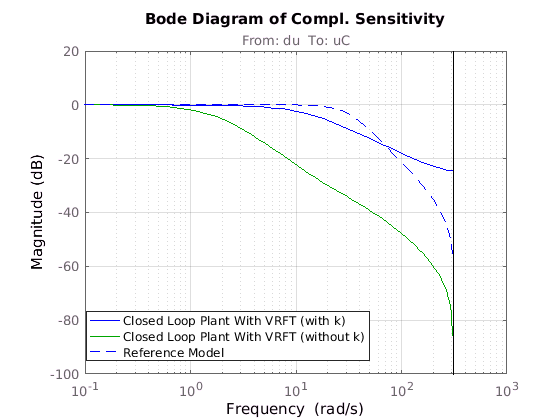



cloop_k = loopsens(PlantModel_dt, OptimalInnerController); 
InnerLoop_VRFT_k = cloop_k.Ti;

figure()
    bode(InnerLoop_VRFT_k, 'b', InnerLoop_VRFT_default, 'g', ...
         InnerReferenceModel_dt, 'b--', bode_no_phase);
    title('Bode Diagram of Compl. Sensitivity');
     legend({'Closed Loop Plant With VRFT (with k)'
            'Closed Loop Plant With VRFT (without k)'
            'Reference Model'}, 'location', 'SouthWest');
    grid on;

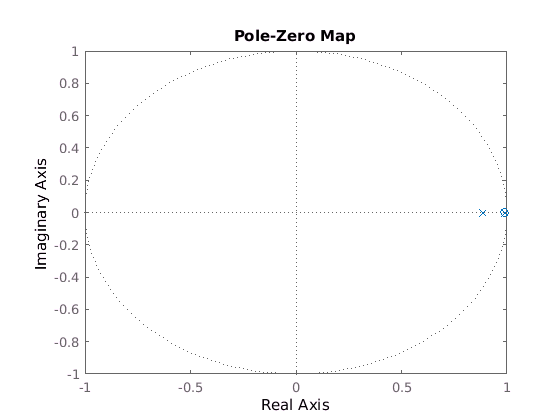

    
figure()
    pzmap(InnerLoop_VRFT_k)

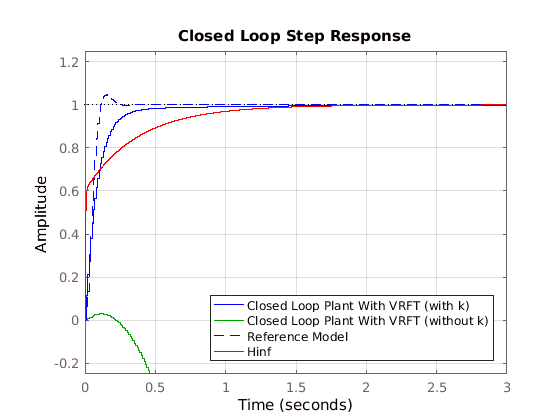

    
figure()
    step(InnerLoop_VRFT_k, 'b', InnerLoop_VRFT_default, 'g', InnerReferenceModel_dt, '--b', ...
        InnerLoop_Hinf, 'r', 3);
    title('Closed Loop Step Response'); ylim([-.25, 1.25]);
    legend({'Closed Loop Plant With VRFT (with k)'
            'Closed Loop Plant With VRFT (without k)'
            'Reference Model'
            'Hinf'}, 'location', 'SouthEast');
    grid on;       

    
InnerLoop_VRFT = InnerLoop_VRFT_k;

For convenience we will save some of the data we used here. In the outer VRFT we will need access to the input and output signals we used to generate the inner controller. We will also keep a copy of the generated controller for obvious reasons.

save('quad_copter_models.mat', ...
    'OptimalInnerController', 'vrft_data', 'InnerLoop_VRFT', ...
    'InnerReferenceModel_dt', 'PlantModel', 'PlantModel_dt', 'USE_REAL_DATA', '-append');